# Acessing Images and Point Cloud Data Using ROS

### Overview

This notebook goes through:

    RGB Images

- Acessing the raw RGB data from the camera (aka. "taking a picture" of what the robot is seeing)

    Point Clouds

- Acessing the raw depth data from the camera ("taking a point cloud")

- Extracting the transformation between robot frames

- Applying a frame transformation to the collected point cloud using `pctransform`

### Acessing Raw RGB Data using ROS

Create a ros subscriber to the `/camera/rgb/image_raw` topic. This is the topic that is used to acess image data from the camera on the robot.

rgb_sub = rossubscriber('/camera/rgb/image_raw','DataFormat','struct');

"Grab" the data that is on the topic at this moment. 

You would want the robot arm to already be in the position where you want to "take a picture" or see what the robot is seeing.

rosImg = receive(rgb_sub);

Read the image data into the varaible `myImg`. 

myImg = rosReadImage(rosImg,"PreserveStructureOnRead",true);

`myImg` should be of size M x N x 3 where M is the number rows of pixels, N is the number of columns of pixels, and 3 is the 1x3 RGB vector for each pixel.

See the image displayed

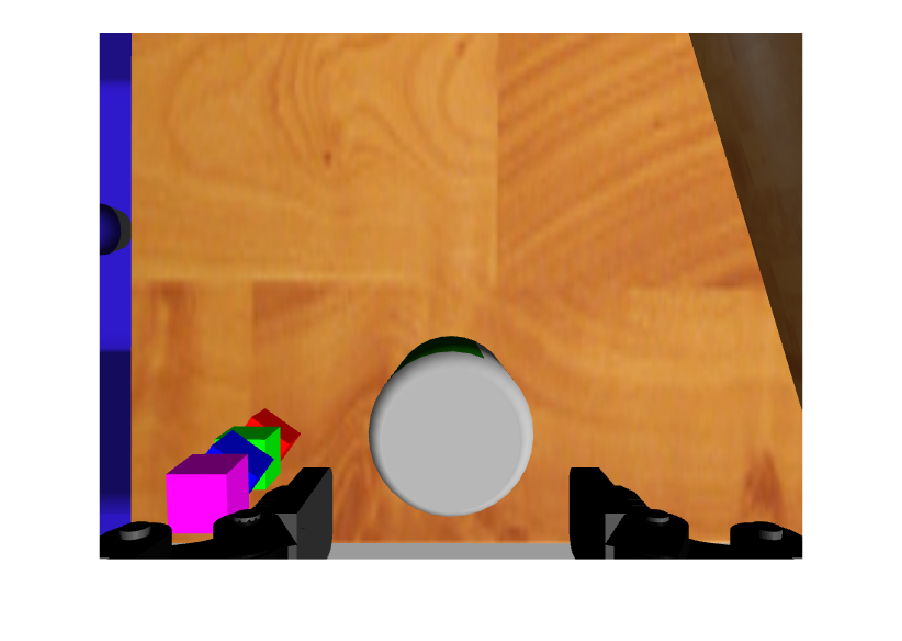

figure, imshow(myImg);

### Acessing Raw Depth Data Using ROS

Create a ros subscriber to the `/camera/depth/points` topic. This is the topic that is used to acess depth data from the camera sensor on the robot.

pt_cloud_sub = rossubscriber('/camera/depth/points','DataFormat','struct');

"Grab" the data that is on the topic at this moment. 

You would want the robot arm to already be in the position where you want to "take a point cloud" or see what the robot is seeing.

pc = receive(pt_cloud_sub,2);

Read the depth data into the variable `xyz`. It should be of size M x N x 3 where M and N should match the M and N of the RGB image M and N.

Then make sure `xyz` is a `pointCloud` object type.

xyz = rosReadXYZ(pc,"PreserveStructureOnRead",true);
ptCloud = pointCloud(xyz); % make xyz a pointCloud object

**Take note**: 

`ptCloud` is currently with respect to the `c``amera_depth_link` instead of the r**obot **`base_link` or the `world`.

### Transforming point cloud data to another frame

Create `tftree` variable

tftree = rostf('DataFormat','struct');    

Specify the frames you want the transformation of

base_frame = 'base_link';
cam_frame = pc.Header.FrameId; %'camera_depth_link';

Compute the ROS/Gazebo transform from base_link to camera_depth_link of the robot arm in the current position.

waitForTransform(tftree, base_frame, cam_frame);
base_to_camera = getTransform(tftree, base_frame, cam_frame, rostime('now'),'Timeout', 5);%r.tf_listening_time);

#### base_to_camera 4x4 matrix

Make a `pos` variable from the translation

pos = [ base_to_camera.Transform.Translation.X, ... 
        base_to_camera.Transform.Translation.Y, ...
        base_to_camera.Transform.Translation.Z]; 

Use `base_to_camera` rotation and format into `q`

q = UnitQuaternion(base_to_camera.Transform.Rotation.W, ...
                   [base_to_camera.Transform.Rotation.X, ...
                    base_to_camera.Transform.Rotation.Y, ...
                    base_to_camera.Transform.Rotation.Z]);

Compute the 4x4 pose for base to camera

q.T; % converts quaternion into homogenous transformation
base_to_cam_pose = transl(pos) * q.T   % now a 4x4

base_to_cam_pose =     1.0000   -0.0000   -0.0008    0.0225
   -0.0000   -1.0000    0.0008   -0.6086
   -0.0008   -0.0008   -1.0000    0.2484
         0         0         0    1.0000


#### Transform the point cloud

Transform the point cloud to `base_link`

tform = rigidtform3d(base_to_cam_pose); % make the transformation of type rigidtform3d so pctransform can use it
ptCloud_tform = pctransform(ptCloud,tform); 